% dynamics
%xdot = Ax + Bu
G = 6.6743 * 10^(-11);
Me = 5.97219 * 10^(24);
r = 4.2165 * 10^4;
grav = G * Me / r^3

grav = 5.3172


A = [0, 0, 0, 1, 0, 0;
    0, 0, 0, 0, 1, 0;
    0, 0, 0, 0, 0, 1;
    3 * grav, 0, 0, 0, 2 * sqrt(grav), 0;
    0, 0, 0, -2 * sqrt(grav), 0, 0;
    0, 0, -grav, 0, 0, 0]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
   15.9516         0         0         0    4.6118         0
         0         0         0   -4.6118         0         0
         0         0   -5.3172         0         0         0


B = [0, 0, 0;
    0, 0, 0;
    0, 0, 0;
    1, 0, 0;
    0, 1, 0;
    0, 0, 1]

B =      0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



% unsafe control
Q = 10 * eye(6);
R = eye(3);

K = lqr(A,B,Q,R);

% simulate
tspan = [0 10]

tspan =      0    10


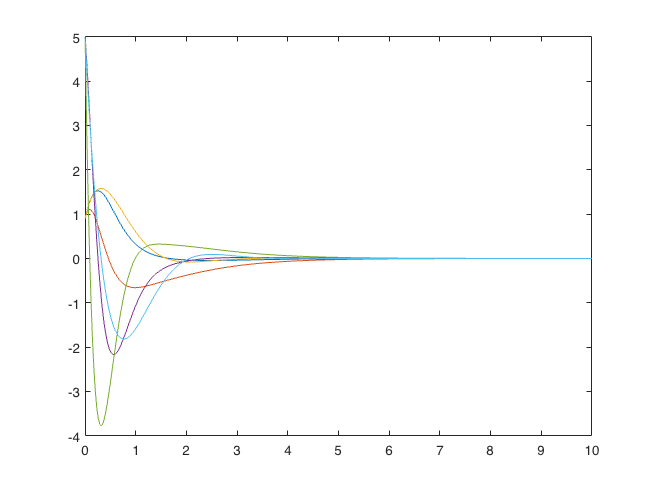

x0 = [0.9; 0.9; 0.9; 5; 5; 5]; % x, y, z, zd, yd, zd
[T,X] = ode45(@(t,x) unsafe_sol(t, x, A, B, K), tspan, x0);

plot(T,X)

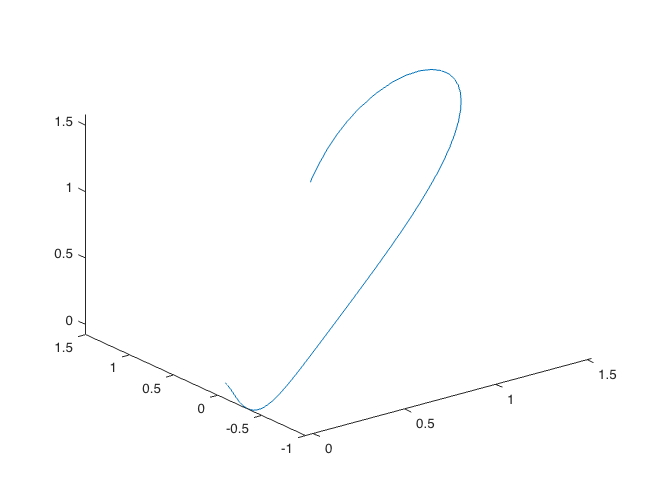

%hold on
plot3(X(:,1), X(:,2), X(:,3))

%axis equal

% linear embedded system
h0 = [1 - 0;
    1 - 0;
    1 - 0];
h02 = h0' * h0

h02 = 3

hx0 = [-1, 0, 0, 0, 0, 0;
    0, -1, 0, 0, 0, 0;
    0, 0, -1, 0, 0, 0];
gamma = 1;

% -gamma * h0
% hx0 * (A * x0 + B * [0; 0; 0]) + hx0 * B * [0; 0; 0]
% hx0 * B * [0; 0; 0]

Az1 = -1/(h02) * hx0 * A - gamma * 1/(h02) * hx0

Az1 =     0.3333         0         0    0.3333         0         0
         0    0.3333         0         0    0.3333         0
         0         0    0.3333         0         0    0.3333


Az2 = -diag([1, 1, 1]);
Bz = -1/(h02) * hx0 * B

Bz =      0     0     0
     0     0     0
     0     0     0


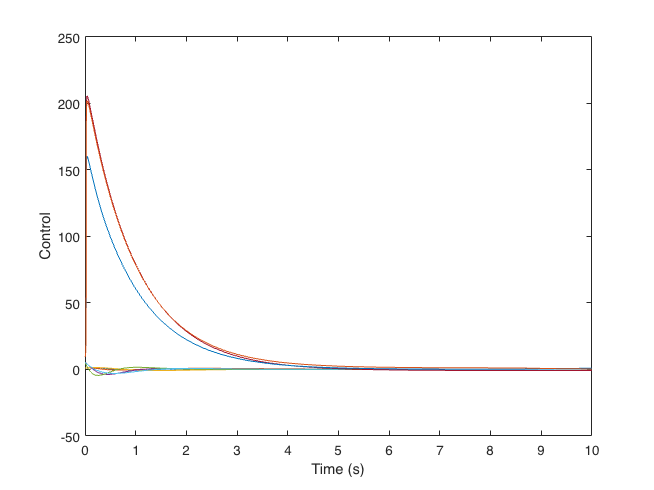


Abar = [A zeros(6,3); Az1 Az2];
Bbar = [B;Bz];
Qbas = diag([10, 1, 2]);
Qbar = [Q zeros(6,3); zeros(3,6) Qbas];

K_safe = lqr(Abar, Bbar, Qbar, R);

z0 = [1 ./ (1 - x0(1)), 1./(1 - x0(2)), 1./(1 - x0(3))]' - 1./h0;
%z0 = 1 ./ (1 - x0(1)) + 1./(1 - x0(2)) + 1./(1 - x0(3)) - 1./h0;
xbar0 = [x0;z0];

[T_safe,X_safe] = ode45(@(t,x) safe_sol(t, x, A, B, K_safe, gamma, h0), tspan, xbar0);
plot(T_safe,X_safe)
xlabel('Time (s)')
ylabel('Control')

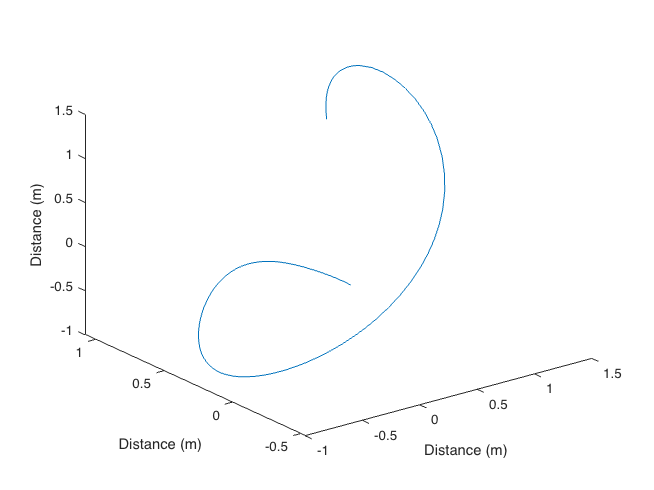

%hold on
plot3(X_safe(:,1), X_safe(:,2), X_safe(:,3))
% hold on
% plot3(X(:,1), X(:,2), X(:,3))
% legend('Safe', 'Unsafe')
xlabel('Distance (m)')
ylabel('Distance (m)')
zlabel('Distance (m)')

max(X_safe(:,1))

ans = 1.3077

max(X_safe(:,2))

ans = 1.0738

max(X_safe(:,3))

ans = 1.3459


min(X_safe(:,1))

ans = -0.8332

min(X_safe(:,2))

ans = -0.5343

min(X_safe(:,3))

ans = -0.9352

## ode funcs

function dx = unsafe_sol(t, x, A, B, K)
u = -K * x;
dx = A*x + B*u;
end

function dx = safe_sol(t, x, A, B, K, gamma, h0)
u = -K * x;
dx = zeros(9,1);

dx(1:6) = A*x(1:6) + B*u;
h = [1 - x(1);
    1 - x(2);
    1 - x(3)];
h2 = h'*h;
hx = [-1, 0, 0, 0, 0, 0;
    0, -1, 0, 0, 0, 0;
    0, 0, -1, 0, 0, 0];
% zdot = -1/(h2) * hx * dx(1:6) - gamma * (x(7:9)' + 1/h0 - 1/h);
% dx(7:9) = zdot(1,1:3)';
zdot = -1/(h2) * hx * dx(1:6) - gamma * (x(7:9)' + 1/h0 - 1/h)';
dx(7:9) = zdot;
end
